% (C) Copyright 2020-2023 Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
clear all; %#ok
close all;
clc

# CoppeliaSim Basics

## Introduction

Before we start to learn how to interface CoppeliaSim with DQ Robotics, it is important to understand some basic concepts of the CoppeliaSim robot simulator.

## CoppeliaSim scenes

A file with extension [.ttt] is a CoppeliaSim scene.

Let us start by opening the scene [engine_behaviour.ttt]. You should see somethig similar to the image bellow.

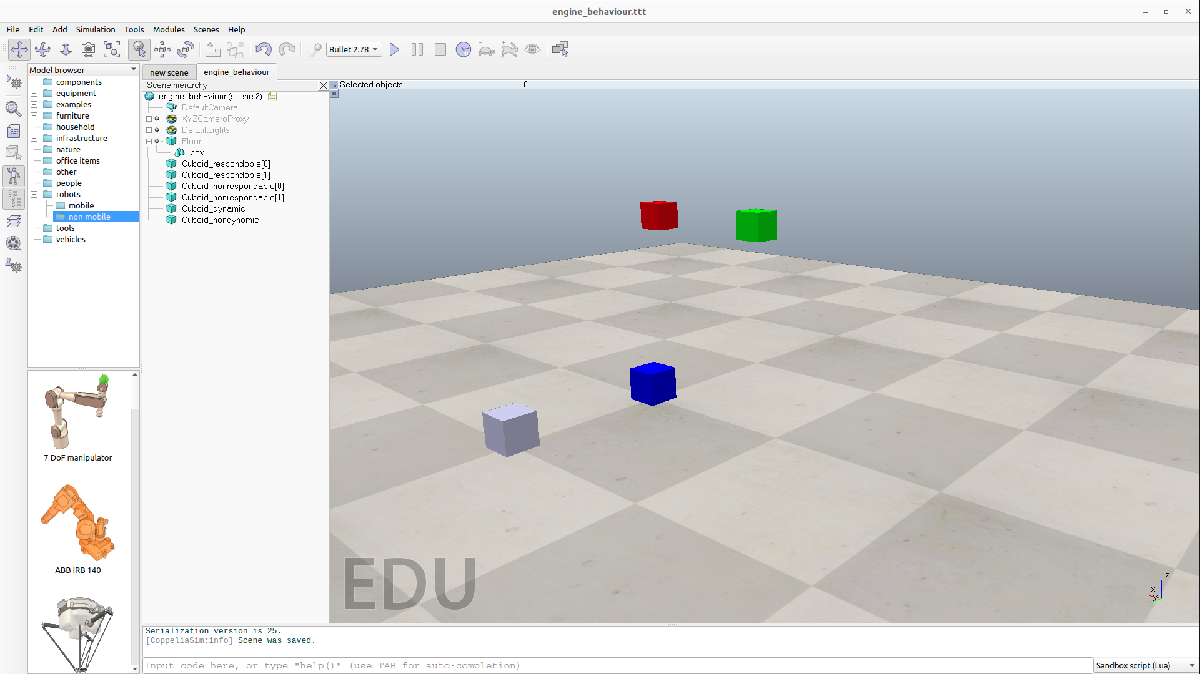

### Simulation control

The top panel allow us to move objects on the scene, select engines, and start/stop the simulation.

You will mostly be using this panel when setting-up new scenes, as, once the simulation is running, it will be more convenient to control it using the interface with DQ Robotics.

### Scene hierarchy

The left side panel shows the scene hierarchy. It lists all objects on the scene, organized by their tree structures. For instance, if you click on the '+' sign on 'Floor,' you will see that this object is the parent of the object 'box,' which, in turn, is a component of 'Floor.'

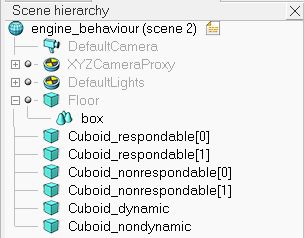

Objects on CoppeliaSim are rigidly attached to their parents. Which means that moving 'Floor' would drag 'box' alongside it, whereas the oposit is not true.

### Static vs dynamic objects

Double click on 'Cuboid[0],' then select 'Dynamic properties dialog' to bring the interface:

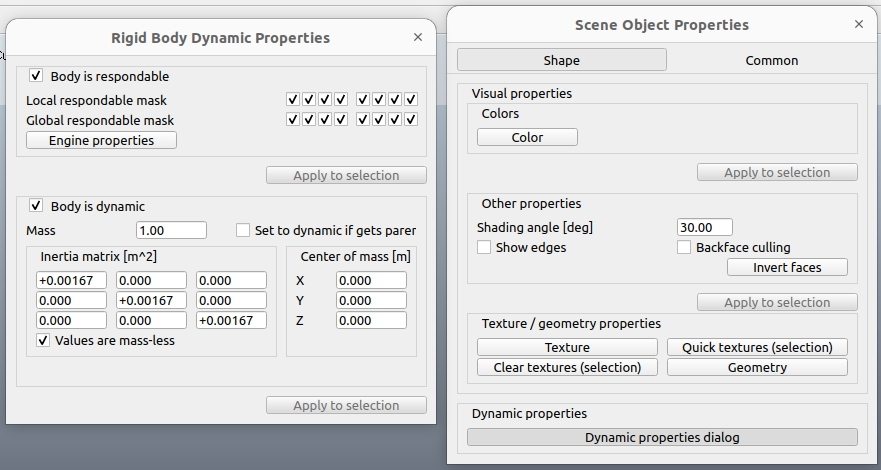

A comprehensive explanation of the 'respondable' and 'dynamic' properties is given in [Shape dynamics properties](https://manual.coppeliarobotics.com/en/shapeDynamicsProperties.htm). However, in brief, you should keep in mind that:

- Objects with the box 'body is respondable' ticked are able to collide with objects with the same respondable mask enabled;

- Objects with the box 'body is dynamic' ticked are subject to dynamic simulation (e.g., will be affected by gravity force).

In the scene [engine_behaviour.ttt], we have a combination of respondable, nonrespondable, dynamic, and nondynamic cubes. 'Cuboid_respondable[0]' is superimposed with 'Cuboid_respondable[1],' whereas 'Cuboid_nonrespondable[0]' is superimposed with 'Cuboid_nonrespondable[1]'. Press the start button and notice how the different bodies behave according to those properties. You can always stop the simulation and replay it again.

### Engine behaviour

The scene [engine_behaviour.ttt] opens with Bullet 2.78 selected as physics engine. Different engines deal differently with all simulation aspects (e.g., with contact). Try to change engines and notice how the superimposed respondable cubes react with each engine.

You can find an extend explanation on the [supported engines](https://manual.coppeliarobotics.com/en/dynamicsModule.htm) and their [differences](https://manual.coppeliarobotics.com/en/physicsEngineDifferences.htm) on CoppeliaSim website. Keep in mind that changing engines might significantly change your simulation results.

### Simulation settings

The simulation settings menu allows you to configure several aspects of the simulation, from the simulation step to gravity acceleration, and even to disable the dynamics entirely.

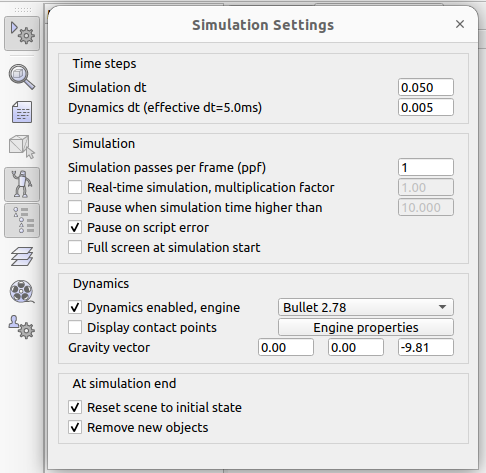

You can familiarize yourself witth all the options checking the [Simulation dialog](https://manual.coppeliarobotics.com/en/simulationPropertiesDialog.htm).

## Adding objects

The 'Add' menu allows you to add primitive shapes, joints, cameras, and such to any scene on CoppeliaSim. Alternativelly, you can also use the 'Model browser' to add more complex objects (e.g., manipulators and mobile robots).

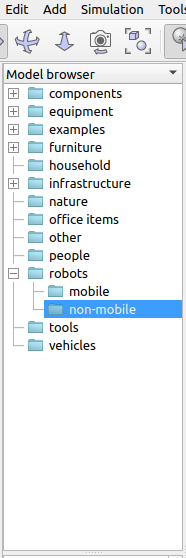

Objects added through the 'Add' menu will appear on the scene at the position [0; 0; 0], whereas objects from the 'Model browser' need to be dragged to the scene. Regardless, you can always change the object's position and orientation later.

## Translating objects

It is easy to translate objects on CoppeliaSim. Simply select an object and click on the 'Object/item shift' button.

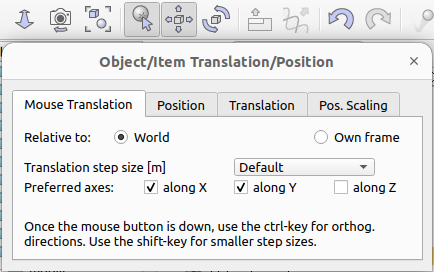

This menu allows you do drag the object on the scene, define it's [x; y; z] coordinates, or translate/scale it along the x/y/z axes.

## Rotating objects

You can rotate objects on CoppeliaSim using the 'Object/item rotate' button.

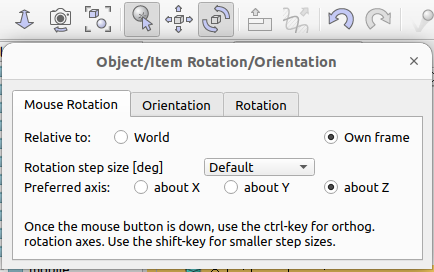

Similar to the options on the translation menu, here you can drag the object, define it's orientation or rotate around the x/y/z axes.

## Configuring joints

Joints can present different operation and control modes.

Open the scene [simple_manipulator.ttt]. You should see somethig similar to the image bellow.

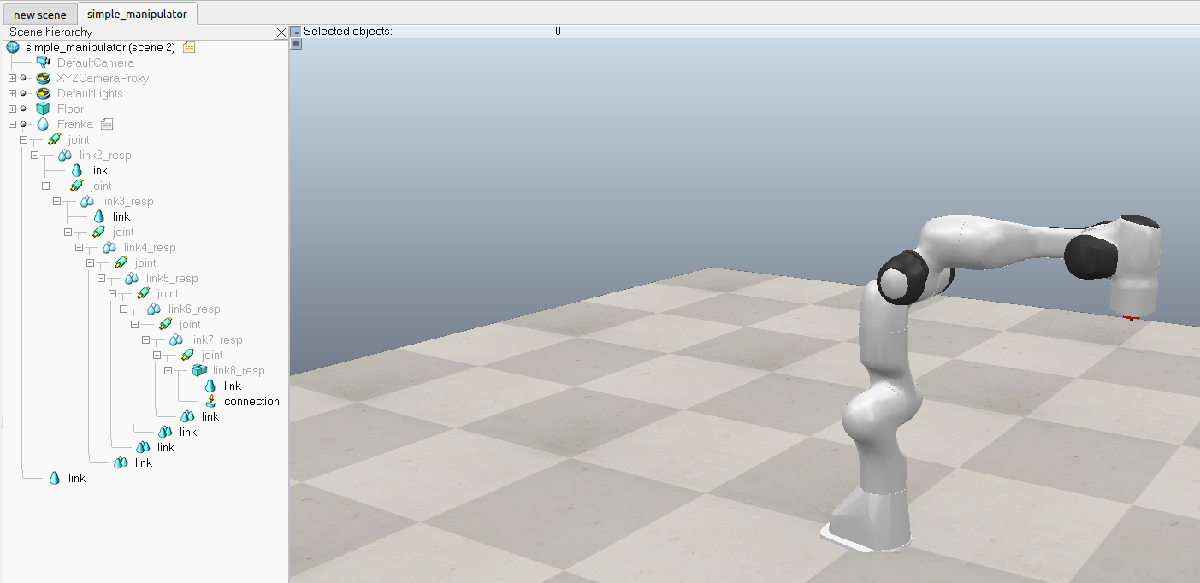

Double click in any joint. This will bring the 'Scene Object Properties' menu. Then click on the 'Dynamic properties dialog' to open the 'Joint Dynamic Properties' menu.

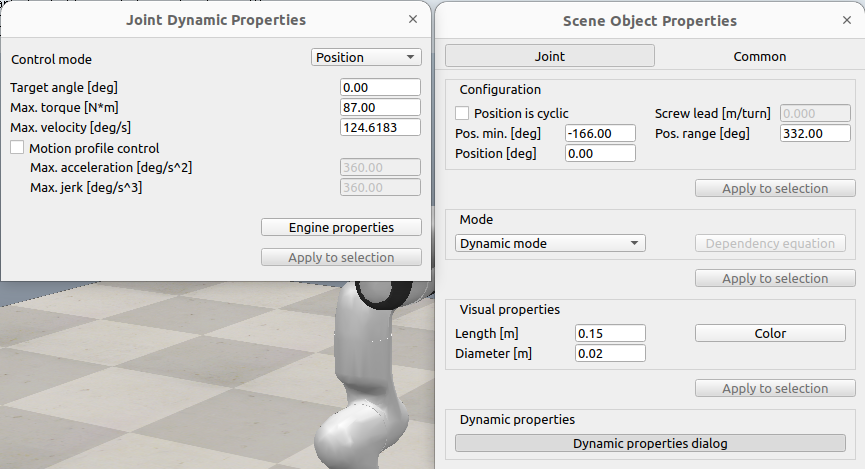

CoppeliaSim provides more documentation on [joint modes](https://manual.coppeliarobotics.com/en/jointModes.htm) and [joint dynamics properties](https://manual.coppeliarobotics.com/en/jointDynamicsProperties.htm). For our lessons, we will use joints on the 'Dynamic mode' with 'Position' and 'Velocity' control modes.

# Homework

- Create a CoppeliaSim scene called [coppeliasim_basics_homework.tt] and, in the same scene, do 2-7.

- Add a Jaco arm robot to the scene.

- Move it to position [0; 0; 0.07837].

- Rotate it by 270° around the z-axis.

- Change the joints from position to velocity control mode.

- Change the physics engine to MuJoCo.

- Bonus: make it so that the robot will not fall when the simulation starts to run.